# Cargar la información con prueba de parámetros 

## Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok


anios = 2000:2022;

Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

### Consulta de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla

tmp = info_hdf.anio >= 2000 & info_hdf.anio <=2022;
%tmp = info_hdf.mes == 9; 
info_consulta = info_hdf(tmp,:);
[filas,~] = size(info_consulta);
disp("Total de imágenes: "+filas);

Total de imágenes: 519


### Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);
% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);
arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 3d de ndvi por día con filtro Saviztky
arr_ndvi_sgf = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 3d de ndvi por día con filtro Lanczos
arr_ndvi_lf = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);


Recuperar toda la información y marcar los dias como baja disponibilidad

bp=waitbar(0,'Obteniendo información'); 
for i=1:filas
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;
    
    %barra de progreso
    waitbar(i/filas,bp,sprintf('Obteniendo información (%3.0f%%) ',(i/filas*100)));
end
close(bp); 


Mostrar el promedio de NDVI de toda la serie

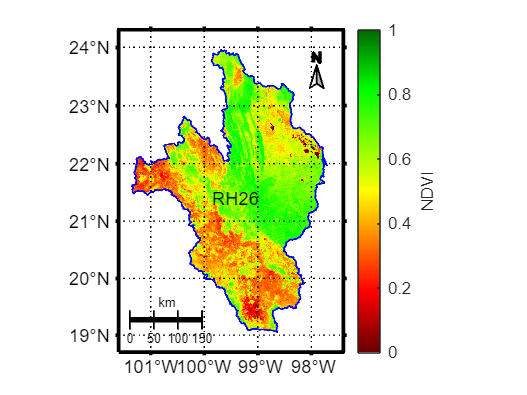

ndvi_prom = m_mean_3dpp(arr_ndvi);
ndvi_prom(area_estudio==false)=nan;

m_dibujar_mapa_ndvi(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"",0);
m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")


disp("Promedio NDVI: "+mean(ndvi_prom,"all","omitnan"));

Promedio NDVI: 0.54383


## Filtrar con Lanczos y Savitzky-Golay 

generar ndvi filtrado

%Mejores parametros para el filtro Lanczos
dT = 23;
cf= 1/46;

% Mejores parametros para Savitzky-Golay
order = 3;
framelen = 7;

bp=waitbar(0,'Generando arr_ndvi con filtros'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if area_estudio(i,j) == true

             S  = reshape( arr_ndvi(i,j,:),[],1);
             SNan =  reshape( arr_ndvi_nan(i,j,:),[],1);

             arr_ndvi_nan(i,j,:) = m_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));

             [xs,~,~,~,~] = lanczosfilter(S,dT,cf,[],'low');  
             arr_ndvi_lf(i,j,:) = xs;

             arr_ndvi_sgf(i,j,:) = sgolayfilt(S,order,framelen);

         end

     end
     waitbar(i/ndvi_tam(1),bp,sprintf('Generando (%3.0f%%) ',(i/ndvi_tam(1)*100)));
end
close (bp);

Mostrar el promedio de NDVI FILTRO LANCZOS de toda la serie

ndvi_prom = m_mean_3dpp(arr_ndvi_lf);
ndvi_prom(area_estudio==false)=nan;

m_dibujar_mapa_ndvi(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"",0);
m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")


disp("Promedio NDVI Filtro: "+mean(ndvi_prom,"all","omitnan"));

Promedio NDVI Filtro: 0.54383


## Regresión lineal por pixel

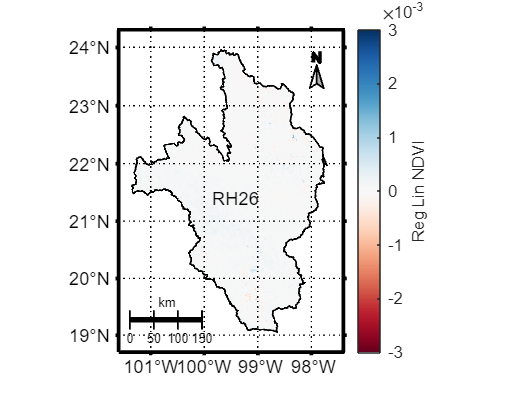


M = arr_ndvi_lf;
tam_arr = size(M);
M = permute(M,[1 3 2]);

ma0 = zeros( tam_arr(1),tam_arr(2));
ma1 = zeros(tam_arr(1),tam_arr(2));

tmp_x = 1:tam_arr(3);

 for i=1:tam_arr(1)
     for j=1:tam_arr(2)
         [ma0(i,j),ma1(i,j),yaj] = m_reglin(tmp_x,M(i,:,j));
     end
 end

 ma1(area_estudio==false)=nan;

 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Regresión lineal de NDVI del 2000 al 2022",[-0.003 0.003], flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","RH26");

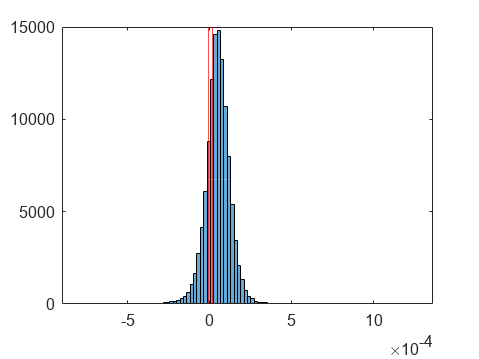

 %m_dibujar_otras_areas(dir_data);
 
 %5%
 %umbral_arriba = 0.0000196;
 %umbral_abajo = -0.0000106;

 %10%
 umbral_arriba = 0.0000166;
 umbral_abajo = -0.00000721;

 figure;
 val_histo = histogram(ma1,100);
 xline(umbral_arriba,"r");
 xline(umbral_abajo,"r");
 
 
 ax = gca;
 exportgraphics(ax,"img/new_reglin_Ssgl.png",'Resolution',300) 

### Contar pixeles con crecimiendo y decremento de NDVI

%%contar pixeles por nivel de NDVI promedio

m1p = zeros(size(ma1));

m1p(ma1 > umbral_arriba) = 3;
m1p(ma1 < umbral_abajo ) = 1;
m1p(ma1 >= umbral_abajo & ma1 <= umbral_arriba) = 2;

c1 = numel(find(m1p==1));
c2 = numel(find(m1p==2));
c3 = numel(find(m1p==3));
% pcolor(m1p); shading interp;
% colorbar;

pc1 = c1/calidad_total*100;
pc2 = c2/calidad_total*100;
pc3 = c3/calidad_total*100;

disp("Sin cambio:  "+pc2+"%");

Sin cambio:  10.7302%


disp("Aumento:     "+pc3+"%");

Aumento:     70.2463%


disp("Disminución: "+pc1+"%");

Disminución: 19.0234%


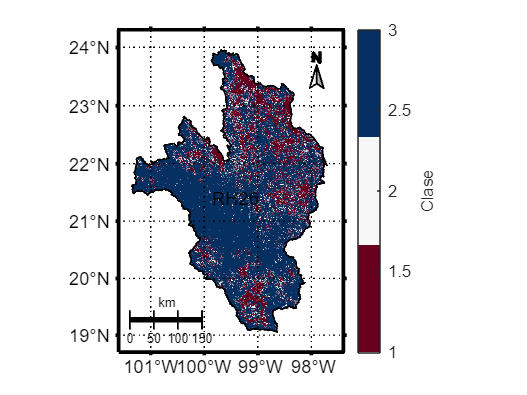



m1p(area_estudio==false)=NaN;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1p,"",[], flipud(m_colmap('diverging',3)) ,"Clase");
 m_dibujar_kml(dir_data,"RH26",1,"k","RH26");
 %m_dibujar_otras_areas(dir_data);
 
 ax = gca;
 exportgraphics(ax,"img/new_reglin_class_Ssgl.png",'Resolution',300) 

### Contar pixeles por valor promedio de NDVI 

%%contar pixeles por nivel de NDVI promedio

m1p = zeros(size(ndvi_prom));

m1p(ndvi_prom == 0)=1;
m1p(ndvi_prom > 0 & ndvi_prom <=0.2) = 2;
m1p(ndvi_prom > 0.2 & ndvi_prom<=0.5) = 3;
m1p(ndvi_prom > 0.5) = 4;

c1 = numel(find(m1p==1));
c2 = numel(find(m1p==2));
c3 = numel(find(m1p==3));
c4 = numel(find(m1p==4));

% pcolor(m1p); shading interp;
% colorbar;

pc1 = c1/calidad_total*100;
pc2 = c2/calidad_total*100;
pc3 = c3/calidad_total*100;
pc4 = c4/calidad_total*100;


disp("NDVI (<0)      : "+pc1+"%");

NDVI (<0)      : 0%


disp("NDVI 0.0 a 0.2 :"+pc2+"%");

NDVI 0.0 a 0.2 :1.0824%


disp("NDVI 0.2 a 0.5 : "+pc3+"%");

NDVI 0.2 a 0.5 : 40.1618%


disp("NDVI > 0.5     : "+pc4+"%");

NDVI > 0.5     : 58.7558%


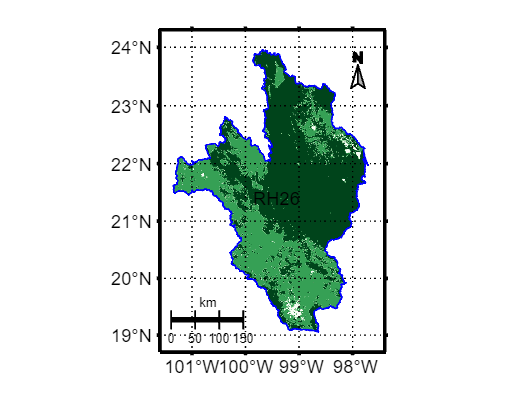



m1p(area_estudio==false)=NaN;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1p,"",[], flipud(m_colmap('green',4)) ,"");
 m_dibujar_kml(dir_data,"RH26",1,"b","RH26");
 %m_dibujar_otras_areas(dir_data);
 
 ax = gca;
 exportgraphics(ax,"img/new_ndvi_class_Ssgl.png",'Resolution',300) ;